## 作业一

### 脚本

读入源图像

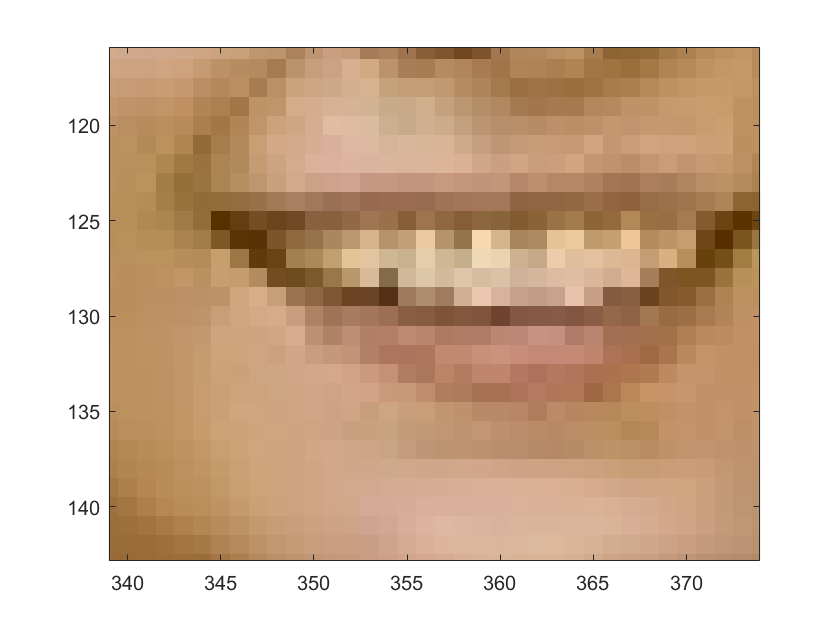

clear,clc;
ori_img = imread("lena.jpg");
canva = uint8(zeros(3000,3000,3));
image(ori_img);

任务(1)： 旋转60度

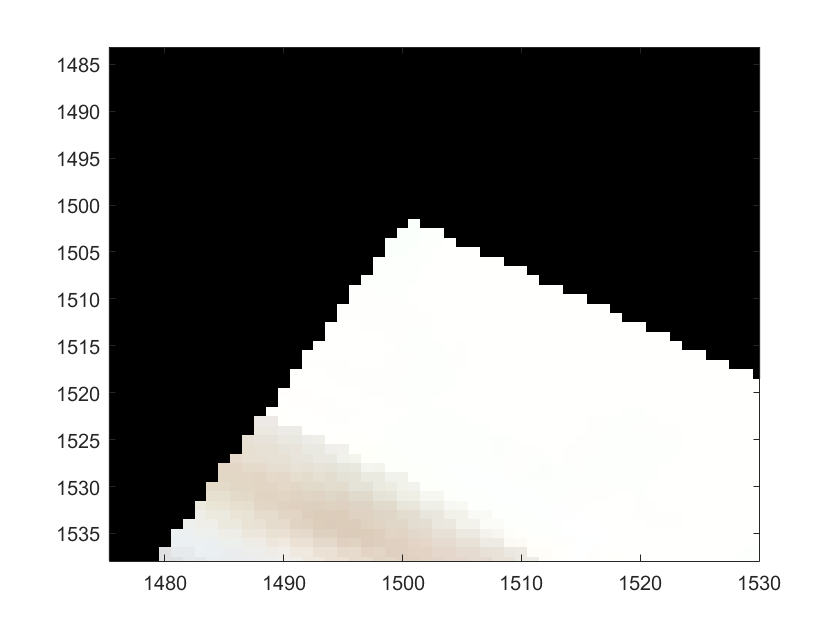

[target,area] = linear2dksquare(getRotate2d(1/6*pi),ori_img,0);
my_show(target,area,canva);

任务（2）缩放变换

依次缩放到原来的0.37与2.13

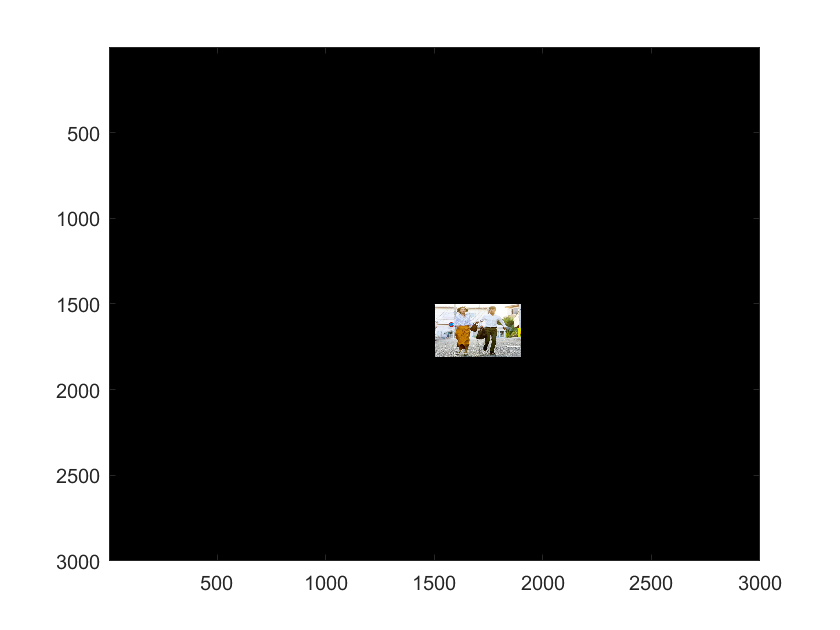

[target,area] = linear2dksquare(getScale([0.37,0.37]),ori_img,0);
my_show(target,area,canva);

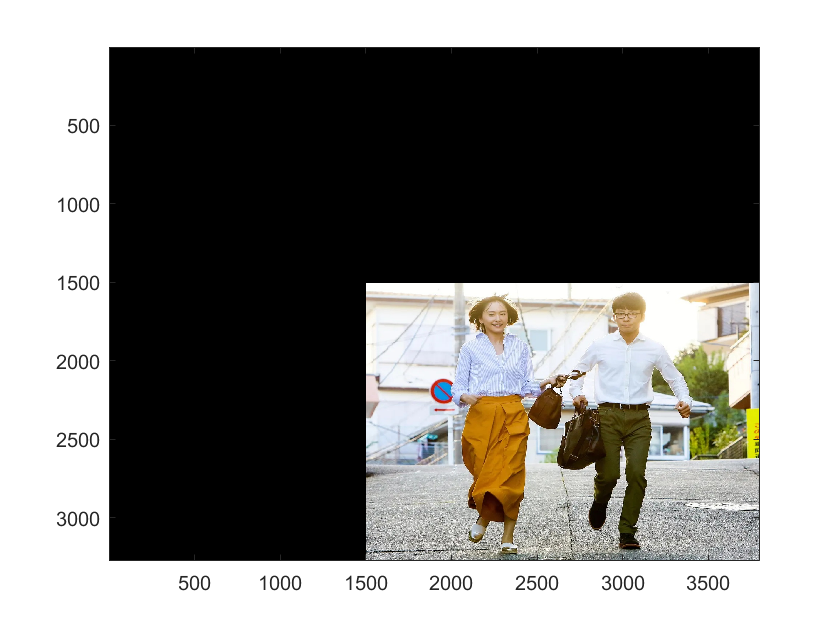

[target,area] = linear2dksquare(getScale([2.13,2.13]),ori_img,0);
my_show(target,area,canva);

任务（3）

依次进行：

- 旋转30度后平移变化

- 旋转30度后缩小到原来的0.5倍

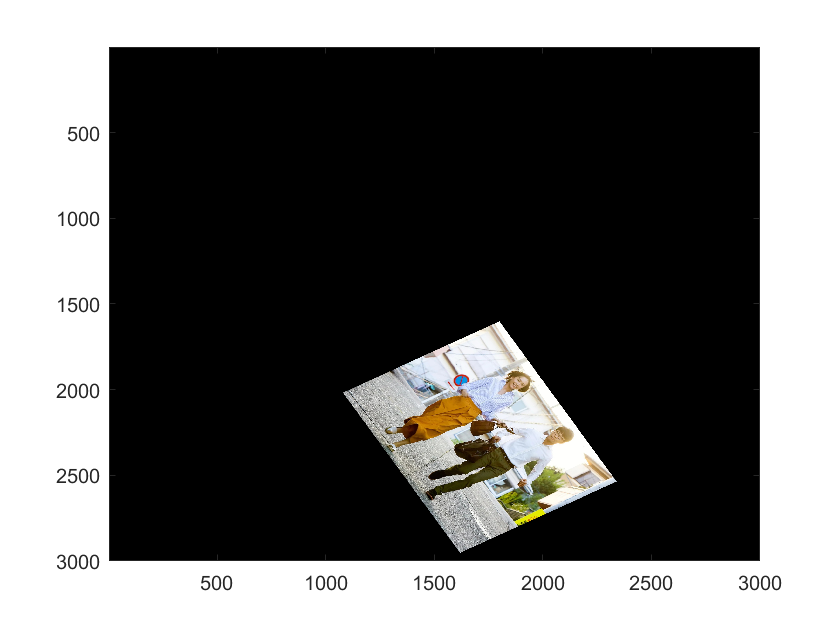

% %仿射
% mat = mat*getaffine2d([1/6*pi 1/6*pi]);
% [target,area] = linear2dksquare(mat,ori_img,0);
% my_show(target,area,canva);
% [target2,area2] = linear2dksquare(mat,ori_img,2);
% my_show(target2,area2,canva);
% 旋转后平移
mat = getTranslate2d([100 300])*getRotate2d(1/3*pi);
[target,area] = linear2dksquare(mat,ori_img,0);
my_show(target,area,canva);

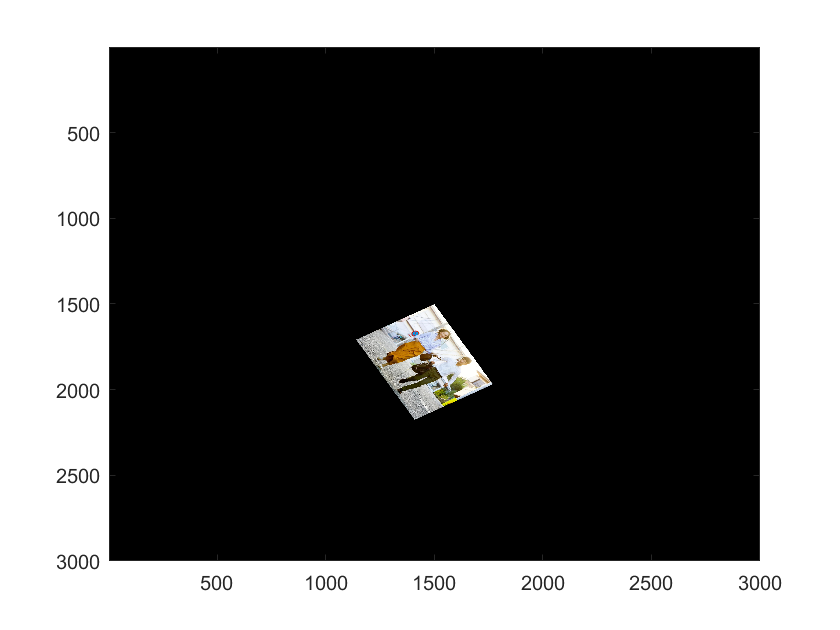

% 旋转后缩小到原来的0.5
mat = getScale([0.5 0.5])*getRotate2d(1/3*pi);
[target,area] = linear2dksquare(mat,ori_img,0);
my_show(target,area,canva);

任务（4）使用双线性插值重复上述步骤

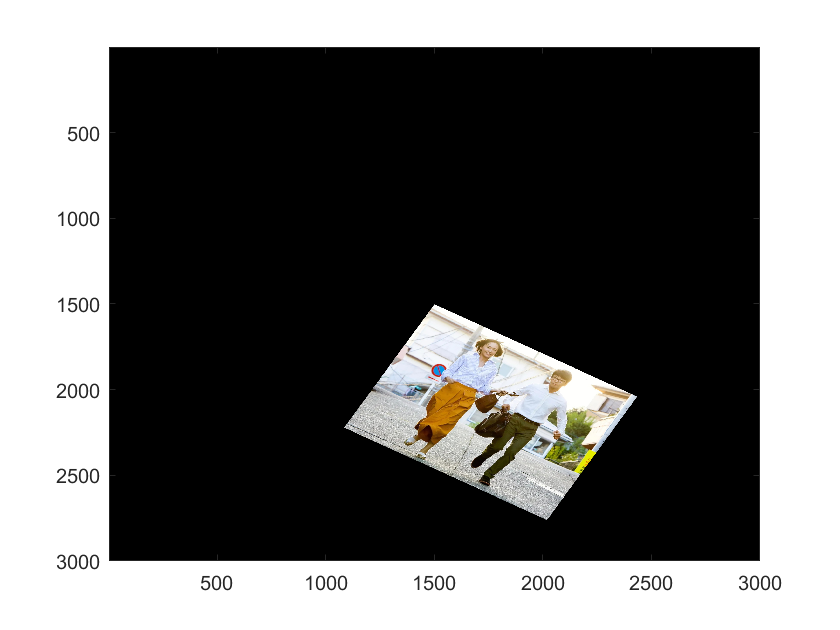

[target,area] = linear2dksquare(getRotate2d(1/6*pi),ori_img,2);
my_show(target,area,canva);

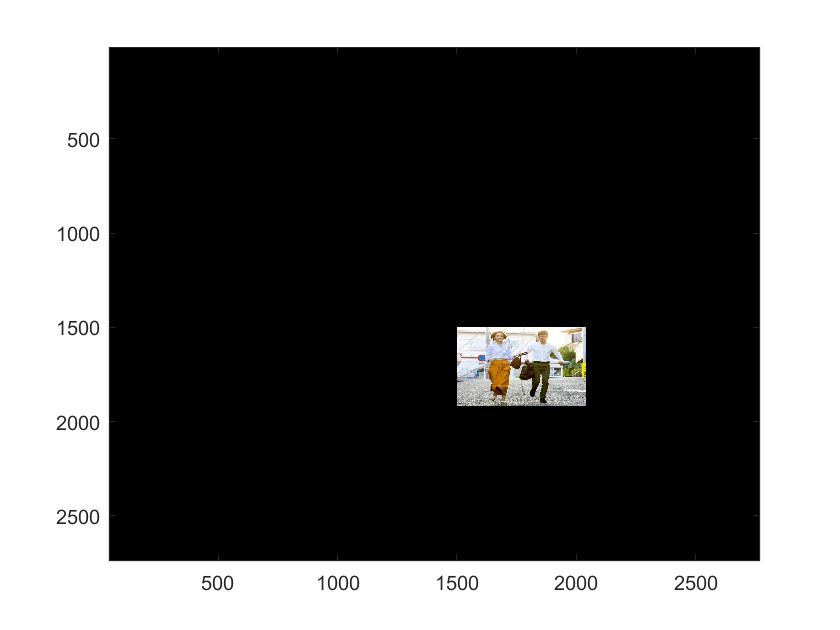


[target,area] = linear2dksquare(getScale([0.5,0.5]),ori_img,2);
my_show(target,area,canva);

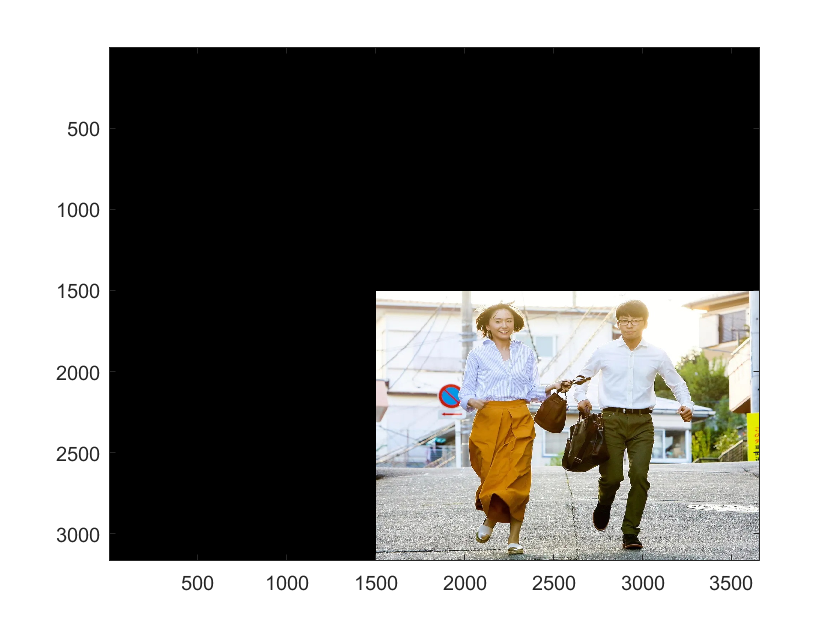

[target,area] = linear2dksquare(getScale([2,2]),ori_img,2);
my_show(target,area,canva);

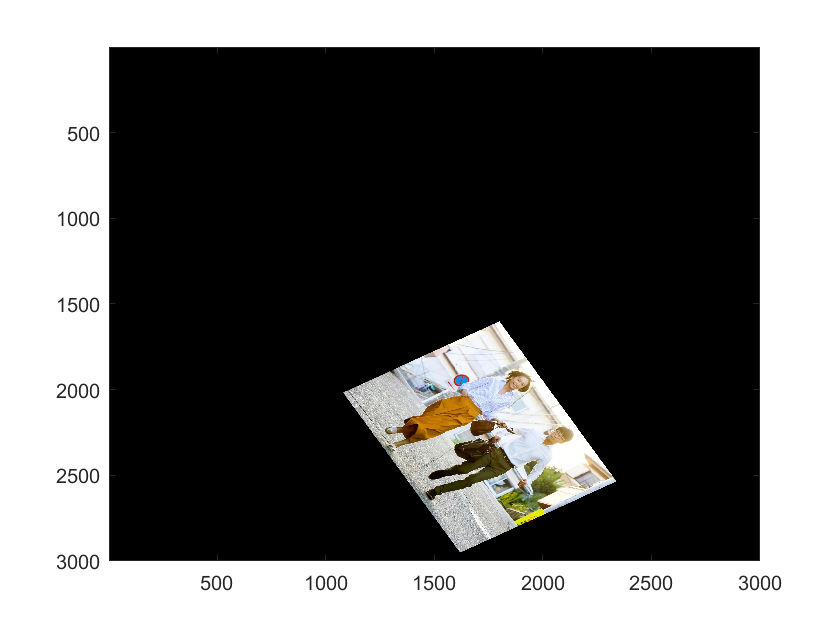


mat = getTranslate2d([100 300])*getRotate2d(1/3*pi);
[target,area] = linear2dksquare(mat,ori_img,2);
my_show(target,area,canva);

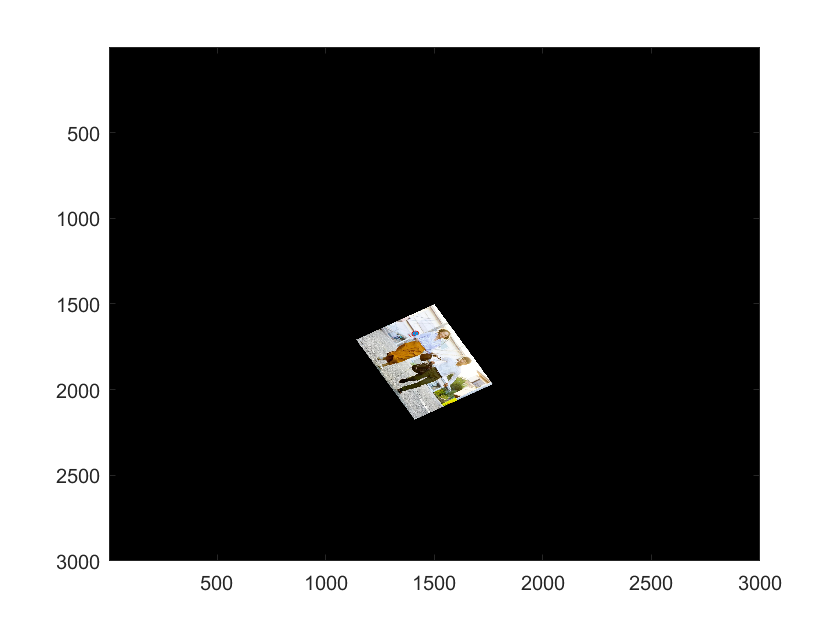

% 旋转后缩小到原来的0.5
mat = getScale([0.5 0.5])*getRotate2d(1/3*pi);
[target,area] = linear2dksquare(mat,ori_img,2);
my_show(target,area,canva);

射影变化的动画

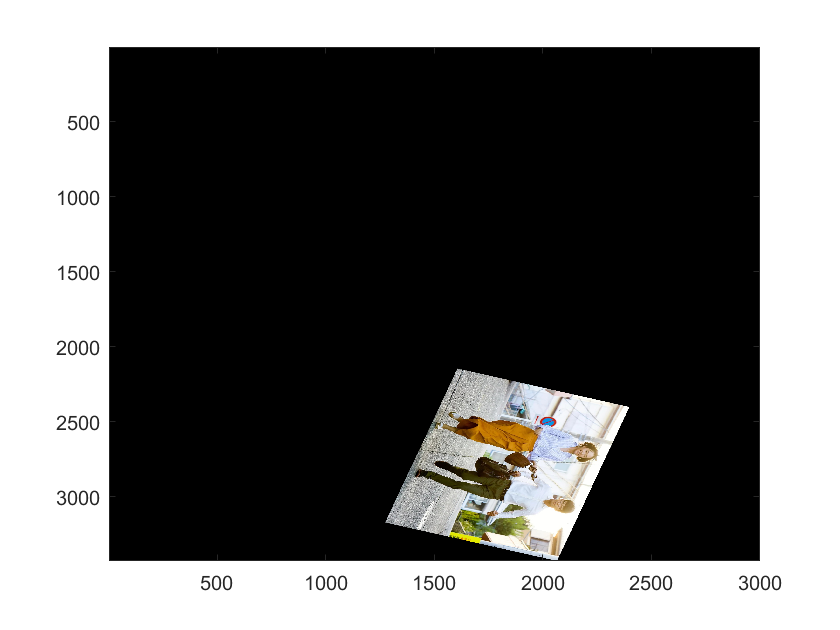

cartoon = figure(1);
pics = cell(1,90);
for i = 1:90
    mat = getTranslate2d([i*10,i*10])*getRotate2d(2*pi*i/300);
    [target,area] = linear2dksquare(mat,ori_img,0);
    pic = my_show(target,area,canva);
    pics{i} = pic;
end

for i = 1:90
    F(i) = im2frame(pics{i});
end
movie(F,10,15)

错误使用 hg2gcv
通过 uifigure 函数创建的图窗不支持该功能。有关详细信息，请参阅 App 设计工具中的图形支持。

出错 movie

出错 movie

出错 movie

save("pics.mat","pics","-v7.3");

### 函数

#### 获取线性变化序列

旋转变化序列

function [mat_seq] = rot_seq(num,rad)
mat_seq = zeros(3,3,num);
    for i = 1:num
        mat_seq(:,:,i) = getRotate2d(rad*i/num);
    end
end

位移变化序列

#### 对一个图像进行线性变换。

- mat 变化矩阵

- points 2*4 四个顶点的像素坐标  **四个顶底顺序固定**

- ori 源图像，

- flag 插值策略 0 1 2 3 分别表示临近、线性插值、双线性插值、三线性插值 。但目前暂时不知道如何在图像变换中使用线性插值，因为像素坐标是二维的

返回：

- target 变化后像素阵列

- npoints 变化后的四个顶点的像素坐标

function [target,area] = linear2dksquare(mat,ori,flag)
[h,w,~] = size(ori);
points = [[1;1;1] [h;1;1] [1;w;1] [h;w;1]];
npoints = mat*points;
nleft = floor(min(npoints(2,:)));
nright = ceil(max(npoints(2,:)));
ntop = floor(min(npoints(1,:)));
nbot = ceil(max(npoints(1,:)));
target = uint8(zeros(nbot-ntop+1,nright-nleft+1,3));
area = [[ntop;nleft] [nbot;nleft] [ntop;nright] [nbot;nright]];

% % 获取源图像像素坐标边界值（在画布中的）
% left =min(points(2,:));
% right = max(points(2,:));
% top = min(points(1,:));
% bot = max(points(1,:));
% % 将坐标原点调整为图片第一个顶点 
% oh = points(1,1);
% ow = points(2,1);
% points(1,:) = points(1,:)-oh;
% points(2,:) = points(2,:)-ow;
% 变成齐次坐标系

% 记录错误像素个数
% e = 0;
% for i = 1:nbot-ntop+1
%     for j = 1:nright-nleft+1
%         % 使用逆矩阵得到目标图样像素在源图像上的采样点的像素坐标
%         % 得到像素坐标直接四舍五入取整；如果对变化后效果有需求则采用插值算法；目前看来取整的效果已经足够
%         sample = fix(mat\[i;j;1]);
%         try
%             target(i,j,:) = source(sample(1),sample(2),:);
%         catch
%             e = e+1;
%         end
%     end
% end
if flag == 0
    for i = ntop:nbot
        for j = nleft:nright
            % 使用逆矩阵得到目标图样像素在源图像上的采样点的像素坐标
            sample = fix(mat\[i;j;1]);
            if h>=sample(1)&&sample(1)>0&&w>=sample(2)&&sample(2)>0
                target(i-ntop+1,j-nleft+1,:) = ori(sample(1),sample(2),:);
            end
        end
    end 
elseif flag == 2
    for i = ntop:nbot
        for j = nleft:nright
            sample = mat\[i;j;1];
            if h>=sample(1)&&sample(1)>=1&&w>=sample(2)&&sample(2)>=1
                sample = sample(1:2);
                s = floor(sample);
                b = ceil(sample);
                ra = (sample(1)-s(1));
                rb = (sample(2)-s(2));
                m = ori(s(1),s(2),:)+ra*(ori(b(1),s(2),:)-ori(s(1),s(2),:));
                n = ori(s(1),b(2),:)+ra*(ori(b(1),b(2),:)-ori(s(1),b(2),:));
                res = m+ (n-m)*rb;
                target(i-ntop+1,j-nleft+1,:) = res;
            end
        end
    end 
elseif flag == 3
    for i = ntop:nbot
        for j = nleft:nright
                                                                                                                                                                                                                                                                                
 
        end
    end 
end
   
 




% % 在res中应用图像
% try
% res(ntop:nbot,nleft:nright,:) = target;    
% catch
% disp("画布未能装下目标图像")
% end
% %变回二维坐标
% npoints = fix(npoints(1:2,:));
end

#### 显示图像

以画布中央为原点显示图像

- target 目标图像矩形像素阵列

- area 目标图像矩形边界

- canva 画布

function [canva] =my_show(target,area,canva)
[h,w,~] = size(canva);
area(1,:) = area(1,:)+ceil(h/2);
area(2,:) = area(2,:)+ceil(w/2);
canva(area(1,1):area(1,4),area(2,1):area(2,4),:) = target;
image(canva);
end

#### 旋转矩阵获取函数

获取旋转矩阵

- theta 绕z轴逆时针的弧度制旋转量

function [mat] = getRotate2d(theta)
    mat = [cos(theta) sin(theta) 0; -1*sin(theta) cos(theta) 0;0 0 1];
end

获取平移矩阵

- dist 1*2矩阵 代表位移[x;y]

function [mat] = getTranslate2d(dist)
    mat = [1 0 dist(1);0 1 dist(2);0 0 1];
end

获取仿射变化矩阵

- offset 1*2矩阵 代表轴旋转量的正切值(而非角度值)

function [mat] = getaffine2d(theta)
    mat = [1 tan(theta(1)) 0;tan(theta(2)) 1 0;0 0 1];
end

获取放缩矩阵

- rate 1*2矩阵 代表高度、宽度放缩量

function [mat] = getScale(rate)
    mat = [rate(1) 0 0;0 rate(2) 0; 0 0 1];
end